clear all
clc

## Funwork3

Phillipp Gery

## **Problem 1. (4 pts)d**

Start with the non-linear model of the double inverted pendulum on a cart (DIPC) from FunWork 1. Show that there does not exist  ue for 

xe_vals = [0.1 pi/3 pi/4 0 0 0]'

xe_vals =     0.1000
    1.0472
    0.7854
         0
         0
         0



syms theta1 theta2 x_pos theta1_dot theta2_dot x_dot

syms theta1_ddot theta2_ddot x_ddot
syms u x

%get Results from Funwork1 means Model 
load("../Funwork1/Funwork1_Gery_Results.mat");
disp("non-linear model")

non-linear model


disp(f)

$$\begin{array}{l} \left(\begin{array}{c} \dot{x}\\ \theta_{\dot{1}}\\ \theta_{\dot{2}}\\ -\frac{280\,u-981\,\sin\left(2\,\theta_{1}\right)+100\,{\theta_{\dot{1}}}^{2}\,\sin\left(\theta_{1}\right)+45\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{2}\right)-120\,u\,\cos\left(\sigma_{3}\right)+45\,{\theta_{\dot{2}}}^{2}\,\sigma_{1}}{20\,\sigma_{2}}\\ \frac{1575\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)-30411\,\sin\left(\theta_{1}\right)-8829\,\sin\left(\theta_{1}-2\,\theta_{2}\right)+250\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{1}\right)+1400\,u\,\cos\left(\theta_{1}\right)+450\,{\theta_{\dot{1}}}^{2}\,\sin\left(\sigma_{3}\right)-600\,u\,\cos\left(\theta_{1}-2\,\theta_{2}\right)+225\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{50\,\sigma_{2}}\\ -\frac{300\,\sin\left(\theta_{1}-\theta_{2}\right)\,{\theta_{\dot{1}}}^{2}+135\,\sin\left(\sigma_{3}\right)\,{\theta_{\dot{2}}}^{2}-2943\,\sigma_{1}+2943\,\sin\left(\theta_{2}\right)+200\,u\,\cos\left(2\,\theta_{1}-\theta_{2}\right)-200\,u\,\cos\left(\theta_{2}\right)}{75\,\cos\left(2\,\theta_{1}\right)+135\,\cos\left(\sigma_{3}\right)-390} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\theta_{1}-\theta_{2}\right)\\ \sigma_{2}=5\,\cos\left(2\,\theta_{1}\right)+9\,\cos\left(\sigma_{3}\right)-26\\ \sigma_{3}=2\,\theta_{1}-2\,\theta_{2} \end{array}$$

eq_point_states = [x_pos, theta1, theta2, x_dot, theta1_dot, theta2_dot];

Set the acceleration components to zero to form our equations

Equations to satisfy for accelerations to be zero:

Subs xe and solve for u

f_at_xe = subs(f, state_vector, xe_vals);
accel_eqns = f_at_xe(4:6) == 0;
sol = solve(accel_eqns, u);

disp(accel_eqns);

$$\begin{array}{l} \left(\begin{array}{c} \frac{60\,\sqrt{3}\,u-280\,u+\frac{981\,\sqrt{3}}{2}}{20\,\sigma_{1}}=0\\ \frac{700\,u-300\,\sqrt{3}\,u-\frac{30411\,\sqrt{3}}{2}+\frac{8829}{2}}{50\,\sigma_{1}}=0\\ \frac{100\,\sqrt{2}\,u-\frac{2943\,\sqrt{2}}{4}+\frac{2943\,\sqrt{6}}{4}+200\,u\,\left(\frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4}\right)}{\frac{135\,\sqrt{3}}{2}-\frac{855}{2}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{9\,\sqrt{3}}{2}-\frac{57}{2} \end{array}$$

Solve for a single u

sol = solve(accel_eqns, u)

 
sol =
 
Empty sym: 0-by-1
 


if isempty(sol)
    disp('Result: The solver returned an empty set. No single solution for u exists.');
else
    disp('Result: A solution was found:');
    disp(sol);
end

Result: The solver returned an empty set. No single solution for u exists.


To demonstrate the conflict, we solve each u from each equation separately:

u_from_eq1 = double(solve(accel_eqns(1), u)); % For x_ddot = 0
u_from_eq2 = double(solve(accel_eqns(2), u)); % For theta1_ddot = 0
u_from_eq3 = double(solve(accel_eqns(3), u)); % For theta2_ddot = 0

disp("Force 'u' required to make x_ddot = 0: " + u_from_eq1);

Force 'u' required to make x_ddot = 0: 4.825


disp("Force 'u' required to make theta1_ddot = 0: " + u_from_eq2);

Force 'u' required to make theta1_ddot = 0: 121.5302


disp("Force 'u' required to make theta2_ddot = 0: " + u_from_eq3);

Force 'u' required to make theta2_ddot = 0: -8.4957


In Summary no Solution!!

## **Problem 2.**

** (4 pts) **Add an extra input in the non-linear DIPC model, namely, the torque at the first joint. Thus the system's input is

where  is the force applied to the cart and  is the torque applied at the first joint. In summary, we now have a three-output two-input system. 

Show that there is no  that would make  an equilibrium state.

Load Solution of Funwork2 and same steps than in Problem 1

load("../Funwork2/Funwork2_Gery_Results.mat");
disp(f_u2)

$$\begin{array}{l} \left(\begin{array}{c} \dot{x}\\ \theta_{\dot{1}}\\ \theta_{\dot{2}}\\ -\frac{280\,u_{1}-981\,\sin\left(2\,\theta_{1}\right)+100\,{\theta_{\dot{1}}}^{2}\,\sin\left(\theta_{1}\right)+45\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{2}\right)-120\,u_{1}\,\cos\left(\sigma_{4}\right)-560\,u_{2}\,\cos\left(\theta_{1}\right)+45\,{\theta_{\dot{2}}}^{2}\,\sigma_{1}+240\,u_{2}\,\sigma_{2}}{20\,\sigma_{3}}\\ \frac{1200\,u_{2}\,\cos\left(2\,\theta_{2}\right)-8829\,\sin\left(\theta_{1}-2\,\theta_{2}\right)-30411\,\sin\left(\theta_{1}\right)-7600\,u_{2}+1575\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)+250\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{1}\right)+1400\,u_{1}\,\cos\left(\theta_{1}\right)+450\,{\theta_{\dot{1}}}^{2}\,\sin\left(\sigma_{4}\right)-600\,u_{1}\,\sigma_{2}+225\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{50\,\sigma_{3}}\\ -\frac{300\,\sin\left(\theta_{1}-\theta_{2}\right)\,{\theta_{\dot{1}}}^{2}+135\,\sin\left(\sigma_{4}\right)\,{\theta_{\dot{2}}}^{2}-2943\,\sigma_{1}+2943\,\sin\left(\theta_{2}\right)+200\,u_{1}\,\cos\left(2\,\theta_{1}-\theta_{2}\right)+400\,u_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-200\,u_{1}\,\cos\left(\theta_{2}\right)-1360\,u_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{75\,\cos\left(2\,\theta_{1}\right)+135\,\cos\left(\sigma_{4}\right)-390} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\theta_{1}-\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{1}-2\,\theta_{2}\right)\\ \sigma_{3}=5\,\cos\left(2\,\theta_{1}\right)+9\,\cos\left(\sigma_{4}\right)-26\\ \sigma_{4}=2\,\theta_{1}-2\,\theta_{2} \end{array}$$

f_u2_at_xe = subs(f_u2, state_vector, xe_vals);
accel_eqns = f_u2_at_xe(4:6) == 0;
sol = solve(accel_eqns, input_vector);

disp(accel_eqns);

$$\begin{array}{l} \left(\begin{array}{c} \frac{280\,u_{2}-280\,u_{1}+60\,\sqrt{3}\,u_{1}-120\,\sqrt{3}\,u_{2}+\frac{981\,\sqrt{3}}{2}}{20\,\sigma_{1}}=0\\ -\frac{7600\,u_{2}-700\,u_{1}+300\,\sqrt{3}\,u_{1}+\frac{30411\,\sqrt{3}}{2}-\frac{8829}{2}}{50\,\sigma_{1}}=0\\ \frac{100\,\sqrt{2}\,u_{1}-\frac{2943\,\sqrt{2}}{4}+\frac{2943\,\sqrt{6}}{4}+200\,u_{1}\,\sigma_{2}-400\,u_{2}\,\sigma_{2}+1360\,u_{2}\,\left(\frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4}\right)}{\frac{135\,\sqrt{3}}{2}-\frac{855}{2}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{9\,\sqrt{3}}{2}-\frac{57}{2}\\ \sigma_{2}=\frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4} \end{array}$$

Attempting to solve for a single u-Vector

sol = solve(accel_eqns, input_vector);
if isempty(sol.u1)
    disp('Result: The solver returned an empty set. No single solution for [u1; u2] exists.');
else
    disp('Result: A solution was found:');
    disp(sol);
end

Result: The solver returned an empty set. No single solution for [u1; u2] exists.


In Summary **no Solution!!** same case than in previous problem

## **Problem 3. (4 pts)** 

Add the third extra input in the non-linear DIPC model, namely, the torque at the second joint. Thus the system's input is where  is the force applied to the cart,  is the torque applied at the first joint, and  is the torque applied at the second joint. In summary, we now have a three-output three-input system. Find  that makes an equilibrium state.

% add sys for the new input and params because again without subs
syms u1 u2 u3
syms M m1 m2 l1 l2 g
%Values of parmas
M_val = 1.5; 
m1_val = 0.5;
m2_val = 0.75;
l1_val = 0.5;
l2_val = 0.75;
g_val = 9.81;
%input vector update
input_vector = [u1; u2; u3];

Because u3 is the tourqe on the first stick ist Q_2 of the Lagraian EoM

--> nessary to Update direct chnage in the nonlinear Model hard because of all the simplifications in the equation


% EOM --> x with u1
eq1 = (M + m1 + m2) * x_ddot ...
      + (m1 + m2) * l1 * theta1_ddot * cos(theta1) ...
      + m2 * l2 * theta2_ddot * cos(theta2) ...
      - (m1 + m2) * l1 * theta1_dot^2 * sin(theta1) ...
      - m2 * l2 * theta2_dot^2 * sin(theta2) ...
      - u1 == 0

$$eq1 = -l_{1}\,\sin\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)\,{\theta_{\dot{1}}}^{2}-l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,{\theta_{\dot{2}}}^{2}-u_{1}+\ddot{x}\,\left(M+m_{1}+m_{2}\right)+l_{1}\,\theta_{\ddot{1}}\,\cos\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)+l_{2}\,m_{2}\,\theta_{\ddot{2}}\,\cos\left(\theta_{2}\right)=0$$


% EOM --> theta1 with added u2
eq2 = (m1 + m2) * l1^2 * theta1_ddot...
      + (m1 + m2) * l1 * x_ddot * cos(theta1) ...
      + m2 * l1 * l2 * theta2_ddot * cos(theta1 - theta2) ...
      + m2 * l1 * l2 * theta2_dot^2 * sin(theta1 - theta2) ... 
      - (m1 + m2) * g * l1 * sin(theta1)- u2 == 0

$$eq2 = {l_{1}}^{2}\,\theta_{\ddot{1}}\,\left(m_{1}+m_{2}\right)-u_{2}-g\,l_{1}\,\sin\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)+l_{1}\,\ddot{x}\,\cos\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)+l_{1}\,l_{2}\,m_{2}\,\theta_{\ddot{2}}\,\cos\left(\theta_{1}-\theta_{2}\right)+l_{1}\,l_{2}\,m_{2}\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)=0$$


% EOM --> theta2 
eq3 = m2 * l2^2 * theta2_ddot ...
      + m2 * l2 * x_ddot * cos(theta2) ...
      + m2 * l1 * l2 * theta1_ddot * cos(theta1 - theta2) ...
      - m2 * l1 * l2 * theta1_dot^2 * sin(theta1 - theta2) ... 
      - m2 * g * l2 * sin(theta2)-u3 == 0

$$eq3 = {l_{2}}^{2}\,m_{2}\,\theta_{\ddot{2}}-u_{3}-g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)+l_{2}\,m_{2}\,\ddot{x}\,\cos\left(\theta_{2}\right)+l_{1}\,l_{2}\,m_{2}\,\theta_{\ddot{1}}\,\cos\left(\theta_{1}-\theta_{2}\right)-l_{1}\,l_{2}\,m_{2}\,{\theta_{\dot{1}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)=0$$

%Solve equations for higthes derviative
eqddot = solve([eq1, eq2, eq3], [x_ddot, theta1_ddot, theta2_ddot]);
% nonlinear System Model f(x,u)
f_u3 = [x_dot;
     theta1_dot;
     theta2_dot;
     eqddot.x_ddot
     eqddot.theta1_ddot;
     eqddot.theta2_ddot;];

%sub into f
f_u3 = simplify(subs(f_u3, {M, m1, m2, l1, l2, g}, {M_val, m1_val, m2_val, l1_val, l2_val, g_val}));
disp(f_u3)

$$\begin{array}{l} \left(\begin{array}{c} \dot{x}\\ \theta_{\dot{1}}\\ \theta_{\dot{2}}\\ -\frac{840\,u_{1}-2943\,\sin\left(2\,\theta_{1}\right)+300\,{\theta_{\dot{1}}}^{2}\,\sin\left(\theta_{1}\right)+135\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{2}\right)-360\,u_{1}\,\cos\left(\sigma_{5}\right)+800\,u_{3}\,\sigma_{2}-1680\,u_{2}\,\cos\left(\theta_{1}\right)-800\,u_{3}\,\cos\left(\theta_{2}\right)+135\,{\theta_{\dot{2}}}^{2}\,\sigma_{1}+720\,u_{2}\,\sigma_{3}}{60\,\sigma_{4}}\\ \frac{3600\,u_{2}\,\cos\left(2\,\theta_{2}\right)-26487\,\sin\left(\theta_{1}-2\,\theta_{2}\right)-91233\,\sin\left(\theta_{1}\right)-22800\,u_{2}+4725\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)+750\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{1}\right)-4000\,u_{3}\,\cos\left(\theta_{1}+\theta_{2}\right)+4200\,u_{1}\,\cos\left(\theta_{1}\right)+1350\,{\theta_{\dot{1}}}^{2}\,\sin\left(\sigma_{5}\right)-1800\,u_{1}\,\sigma_{3}+13600\,u_{3}\,\cos\left(\theta_{1}-\theta_{2}\right)+675\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{150\,\sigma_{4}}\\ -\frac{2700\,\sin\left(\theta_{1}-\theta_{2}\right)\,{\theta_{\dot{1}}}^{2}+1215\,\sin\left(\sigma_{5}\right)\,{\theta_{\dot{2}}}^{2}+13600\,u_{3}-26487\,\sigma_{1}+26487\,\sin\left(\theta_{2}\right)-4000\,u_{3}\,\cos\left(2\,\theta_{1}\right)+1800\,u_{1}\,\sigma_{2}+3600\,u_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-1800\,u_{1}\,\cos\left(\theta_{2}\right)-12240\,u_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{135\,\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\theta_{1}-\theta_{2}\right)\\ \sigma_{2}=\cos\left(2\,\theta_{1}-\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{1}-2\,\theta_{2}\right)\\ \sigma_{4}=5\,\cos\left(2\,\theta_{1}\right)+9\,\cos\left(\sigma_{5}\right)-26\\ \sigma_{5}=2\,\theta_{1}-2\,\theta_{2} \end{array}$$



f_u3_at_xe = subs(f_u3, state_vector, xe_vals);
accel_eqns = f_u3_at_xe(4:6) == 0;
sol = solve(accel_eqns, input_vector);

disp(accel_eqns);

$$\begin{array}{l} \left(\begin{array}{c} \frac{840\,u_{2}-840\,u_{1}+180\,\sqrt{3}\,u_{1}+400\,\sqrt{2}\,u_{3}-360\,\sqrt{3}\,u_{2}+\frac{2943\,\sqrt{3}}{2}+800\,u_{3}\,\sigma_{1}}{60\,\sigma_{2}}=0\\ -\frac{22800\,u_{2}-2100\,u_{1}+900\,\sqrt{3}\,u_{1}+\frac{91233\,\sqrt{3}}{2}+4000\,u_{3}\,\sigma_{1}-13600\,u_{3}\,\sigma_{3}-\frac{26487}{2}}{150\,\sigma_{2}}=0\\ \frac{900\,\sqrt{2}\,u_{1}-15600\,u_{3}-\frac{26487\,\sqrt{2}}{4}+\frac{26487\,\sqrt{6}}{4}+1800\,u_{1}\,\sigma_{1}-3600\,u_{2}\,\sigma_{1}+12240\,u_{2}\,\sigma_{3}}{135\,\sigma_{2}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}}{4}-\frac{\sqrt{6}}{4}\\ \sigma_{2}=\frac{9\,\sqrt{3}}{2}-\frac{57}{2}\\ \sigma_{3}=\frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4} \end{array}$$

Attempting to solve for a  u-Vector

sol = solve(accel_eqns, input_vector);

u1e = double(simplify(sol.u1));
u2e = double(simplify(sol.u2));
u3e = double(simplify(sol.u3));

ue = [u1e; u2e; u3e];
if isempty(sol.u1)
    disp('Result: The solver returned an empty set. No single solution for [u1; u2] exists.');
else
    disp('Result: solution of the Eqiliribium for ue is:');
    disp(ue);
end

Result: solution of the Eqiliribium for ue is:


         0
   -5.3098
   -3.9019



## **Problem 4.**

**(4 pts)** Perform Taylor's linearization about  xe ue

%Jacobians and insert Numerical Values
%Jacobian parcial dervi
A_sym = jacobian(f_u3, state_vector);
B_sym = jacobian(f_u3, input_vector);
% variables and values  at the eq. point
all_sym_vars = [eq_point_states, input_vector.']; % states and input
all_num_vals = [xe_vals', ue']; 
% Substitute all left values
A_at_eq = subs(A_sym, all_sym_vars, all_num_vals);
B_at_eq = subs(B_sym, all_sym_vars, all_num_vals);
% to numerical doubles
A_u3 = double(A_at_eq);
B_u3 = double(B_at_eq);

disp(A_u3); % 

         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -0.5341   -1.1264         0         0         0
         0   22.5046  -17.8041         0         0         0
         0  -13.9883   21.7759         0         0         0



new Jacobian Matrix B (Linarized) for System with 3*u:

disp(B_u3);

         0         0         0
         0         0         0
         0         0         0
    0.4252   -0.1742   -0.2887
   -0.1742    7.3409   -4.5629
   -0.2887   -4.5629    5.5808



Matrix C for System with 3*u stay s the same:

C_u3 = C;
disp(C_u3)

     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0



D_u3 = zeros(3, 3);
disp(D_u3)

     0     0     0
     0     0     0
     0     0     0



## **Problem 5. (8 pts)** 

Design a state-feedback controller, , using LMIs and test it on the non-linear model.

Generate plots of the state variables versus time on the time interval  secs. When performing your simulations you have to use one of MATLAB's *ode* functions, for example, *ode23* or *ode45*. Compare their performance and see if you can notice any differences in your plots. 


n = size(A_u3, 1); 
m = size(B_u3, 2); 

% shift the poles more into the negative half plane 
alpha = 3;% pretty fast ...


cvx_begin sdp 

    % S = P^-1 
    variable S(n, n) symmetric
    % Z = KS 
    variable Z(m, n)
    
    % First LMI: S > 0 (for P to be positive definite)
    S >= eps * eye(n);
    
    S*A_u3' + A_u3*S - Z'*B_u3' -B_u3*Z + alpha*S <= -eps * eye(n);
    
    
cvx_end % Solve the LMI feasibility problem

 
Calling SDPT3 4.0: 60 variables, 21 equality constraints
------------------------------------------------------------

 num. of constraints = 21
 dim. of sdp    var  = 12,   num. of sdp  blk  =  2
 dim. of free   var  = 18 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.1e+02|9.2e+02|2.0e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.859|0.893|5.8e+01|9.9e+01|5.2e+03| 0.000000e+00  4.885395e-14| 0:0:00| chol  1  1 
 2|0.962|0.838|2.2e+00|1.6e+01|3.5e+02| 0.000000e+00  2.891606e-14| 0:0:00| chol  1  1 
 3|1.000|0.971|1.0e-04|4.7e-01|7.1e+00| 0.000000e+00  8.936261e-16| 0:0:01|

disp(['CVX status: ', cvx_status]);

CVX status: Solved


% K = Z * S^-1
K_x = Z / S;

CVX gain matrix K_x:

disp(K_x);

   47.0081    5.6967    7.1171   22.5206    2.6177    3.3318
    4.3810    9.4462    2.1764    2.3274    2.4769    2.0456
    5.5110    1.5970   12.6162    2.9699    1.9779    3.4015



%Check the poles of the closed-loop system
A_cl_cvx = A_u3 - B_u3 * K_x;
poles_cvx = eig(A_cl_cvx);

Poles of the CVX-controlled closed-loop system:

disp(poles_cvx)

  -4.8742 + 6.1042i
  -4.8742 - 6.1042i
  -3.3325 + 0.0000i
  -4.0738 + 0.5677i
  -4.0738 - 0.5677i
  -4.4739 + 0.0000i



if all(real(poles_cvx) < 0)
    disp('Verification successful: The CVX controller is stabilizing.');
else
    disp('Verification failed: The controller is not stabilizing.');
end

Verification successful: The CVX controller is stabilizing.


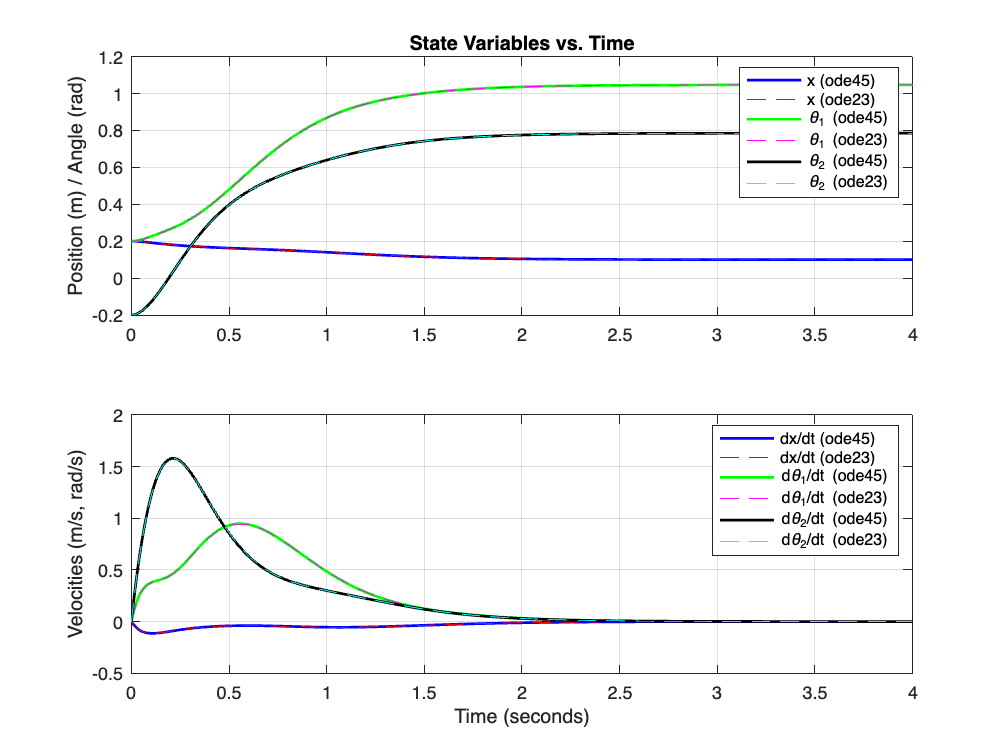

%Simualtion
tspan = [0 4];
x_init = [0.2; 0.2; -0.2; 0; 0; 0]; 

f_handle_3u = matlabFunction(f_u3, 'Vars', {state_vector, input_vector});

system_dynamics = @(t, x) f_handle_3u(x, (-K_x * (x - xe_vals) + ue));

[T45, X45] = ode45(system_dynamics, tspan, x_init);
[T23, X23] = ode23(system_dynamics, tspan, x_init);


figure('Name', 'Non-Linear System Response with LMI Controller');

% Plot Positions and Angles
subplot(2, 1, 1);
plot(T45, X45(:, 1), 'b-', 'LineWidth', 1.5');
hold on;
plot(T23, X23(:, 1), 'r--');
plot(T45, X45(:, 2), 'g-', 'LineWidth', 1.5');
plot(T23, X23(:, 2), 'm--');
plot(T45, X45(:, 3), 'k-', 'LineWidth', 1.5');
plot(T23, X23(:, 3), 'c--');
title('State Variables vs. Time');
ylabel('Position (m) / Angle (rad)');
grid on;
legend('x (ode45)', 'x (ode23)', '\theta_1 (ode45)', '\theta_1 (ode23)', '\theta_2 (ode45)', '\theta_2 (ode23)');

% Plot Velocities
subplot(2, 1, 2);
plot(T45, X45(:, 4), 'b-', 'LineWidth', 1.5');
hold on;
plot(T23, X23(:, 4), 'r--');
plot(T45, X45(:, 5), 'g-', 'LineWidth', 1.5');
plot(T23, X23(:, 5), 'm--');
plot(T45, X45(:, 6), 'k-', 'LineWidth', 1.5');
plot(T23, X23(:, 6), 'c--');
xlabel('Time (seconds)');
ylabel('Velocities (m/s, rad/s)');
grid on;
legend('dx/dt (ode45)', 'dx/dt (ode23)', 'd\theta_1/dt (ode45)', 'd\theta_1/dt (ode23)', 'd\theta_2/dt (ode45)', 'd\theta_2/dt (ode23)');

## Problem 6. 

(4 pts) Use LMIs to design an output-feedback controller, . Generate plots of state variables versus time on the time interval  secs. This can be one figure with  subplots.

p = size(C_u3, 1);

cvx_begin sdp 

    variable P(n, n) symmetric
    % Z = CKS 
    variable N(m, p)
    variable M(m, m)
    
    % First LMI: S > 0 (for P to be positive definite)
    P >= eps * eye(n);
    
    A_u3'*P + P*A_u3 - C_u3' * N' * B_u3' -B_u3 * N * C_u3  <= -eps * eye(n);

    B_u3 * M == P * B_u3
    
cvx_end % Solve the LMI feasibility problem

 
Calling SDPT3 4.0: 60 variables, 39 equality constraints
------------------------------------------------------------

 num. of constraints = 39
 dim. of sdp    var  = 12,   num. of sdp  blk  =  2
 dim. of free   var  = 18 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.1e+02|4.9e+02|1.1e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.688|0.852|1.3e+02|7.2e+01|4.8e+03| 0.000000e+00  5.180223e-14| 0:0:00| chol  1  1 
 2|0.860|0.899|1.8e+01|7.3e+00|3.1e+02| 0.000000e+00  4.103545e-14| 0:0:00| chol  1  1 
 3|0.980|0.980|3.7e-01|1.5e-01|5.1e+00| 0.000000e+00  4.023149e-14| 0:0:00|

disp(['CVX status: ', cvx_status]);

CVX status: Solved


% K = M\N
K_o = M\N;

CVX gain matrix K:

disp(K_o);

    1.6477    0.3186    0.4219
    0.0789    3.8555    0.5858
    0.1047    0.5299    4.9800




%Check the poles of the closed-loop system
A_cl_o = A_u3 - B_u3 * K_o * C_u3;
poles_o = eig(A_cl_o);


Poles of the CVX-controlled closed-loop system:

disp(poles_o)

  -0.0000 + 0.7822i
  -0.0000 - 0.7822i
   0.0000 + 1.6126i
   0.0000 - 1.6126i
   0.0000 + 1.9977i
   0.0000 - 1.9977i



**All  REal(poles) are 0 with means the behaviour is a pure Oscilation ...**

**This is not improvable without a addtional Input or Output**

**Because:**

n <= m+p-1

ans = logical
   0


**Not Satisfyed --> no unique Solution for Controlller  if shifted more  into the negative halfe Plane**

**Because of that no Asymtotical Stabel behaviour **

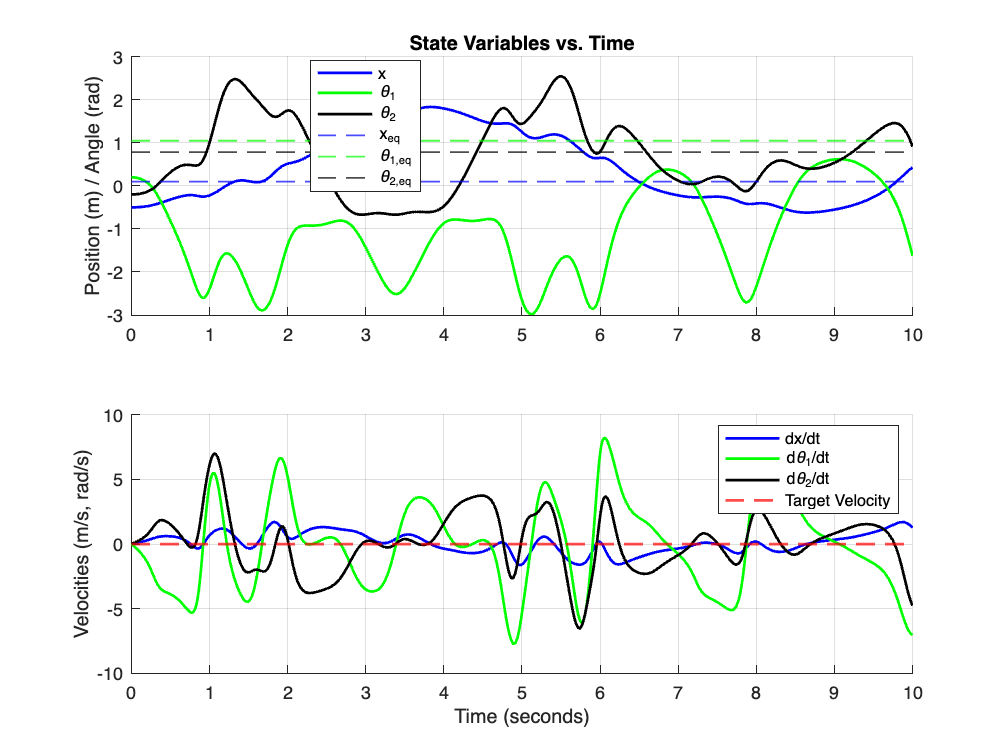


%Simualtion
tspan = [0 10];
x_init = [-0.5; 0.2; -0.2; 0; 0; 0]; 

f_handle_3u = matlabFunction(f_u3, 'Vars', {state_vector, input_vector});

system_dynamics = @(t, x) f_handle_3u(x, -K_o * C_u3 * (x - xe_vals) + ue);

[T45, X45] = ode45(system_dynamics, tspan, x_init);


% Generate Plots with Equilibrium as desiered States
figure('Name', 'Non-Linear System Response with LMI Controller');

% Plot Positions and Angles
subplot(2, 1, 1);
hold on;
% Plot the state trajectories
plot(T45, X45(:, 1), 'b-', 'LineWidth', 1.5);
plot(T45, X45(:, 2), 'g-', 'LineWidth', 1.5);
plot(T45, X45(:, 3), 'k-', 'LineWidth', 1.5);
% Add horizontal lines for the equilibrium points
yline(xe_vals(1), 'b--', 'LineWidth', 1); % Target for x
yline(xe_vals(2), 'g--', 'LineWidth', 1); % Target for theta_1
yline(xe_vals(3), 'k--', 'LineWidth', 1); % Target for theta_2
hold off;
title('State Variables vs. Time');
ylabel('Position (m) / Angle (rad)');
grid on;
legend('x', '\theta_1', '\theta_2', 'x_{eq}', '\theta_{1,eq}', '\theta_{2,eq}', 'Location', 'best');

% Plot Velocities
subplot(2, 1, 2);
hold on;
% Plot the state trajectories
plot(T45, X45(:, 4), 'b-', 'LineWidth', 1.5);
plot(T45, X45(:, 5), 'g-', 'LineWidth', 1.5);
plot(T45, X45(:, 6), 'k-', 'LineWidth', 1.5);
% Add a single horizontal line at zero for the target velocities
yline(0, 'r--', 'LineWidth', 1.5); % Target for all velocities is 0
hold off;
xlabel('Time (seconds)');
ylabel('Velocities (m/s, rad/s)');
grid on;
legend('dx/dt', 'd\theta_1/dt', 'd\theta_2/dt', 'Target Velocity');

## Problem 7. 

(4 pts) Simulate the combined state-feedback controller-observer compensator and compare its performance against the output feedback controller.

Generate plots of state variables versus time, where 

 is an estimate of . Note that you can always set your observer's initial conditions to zero, if you wish, since you have complete access to your design.


% Rule of thumb: Make the observer poles faster than the controller poles.
% We'll make them 3 times faster for a quick convergence.
observer_pole_factor = 3;

p_obs = observer_pole_factor * poles_cvx;

L = place(A_u3', C_u3', p_obs)';


Calculated Observer Gain Matrix L:

disp(L);

   23.4193         0         0
         0   26.1165  -20.3375
         0   13.5709   27.5714
  134.1841   -0.5341   -1.1264
         0  227.5298 -261.0187
         0  148.4279  236.9559




% Verification: Check the observer poles
A_obs_check = A_u3 - L*C_u3;
actual_observer_poles = eig(A_obs_check);

Actual observer poles (Eigenvalues of A-LC):

disp(actual_observer_poles);

 -13.4218 + 0.0000i
  -9.9975 + 0.0000i
 -14.6226 +18.3127i
 -14.6226 -18.3127i
 -12.2214 + 1.7031i
 -12.2214 - 1.7031i



% Simulation time

tspan = [0 5];

Siumlate Oberver with 

detla_x = x - xe 

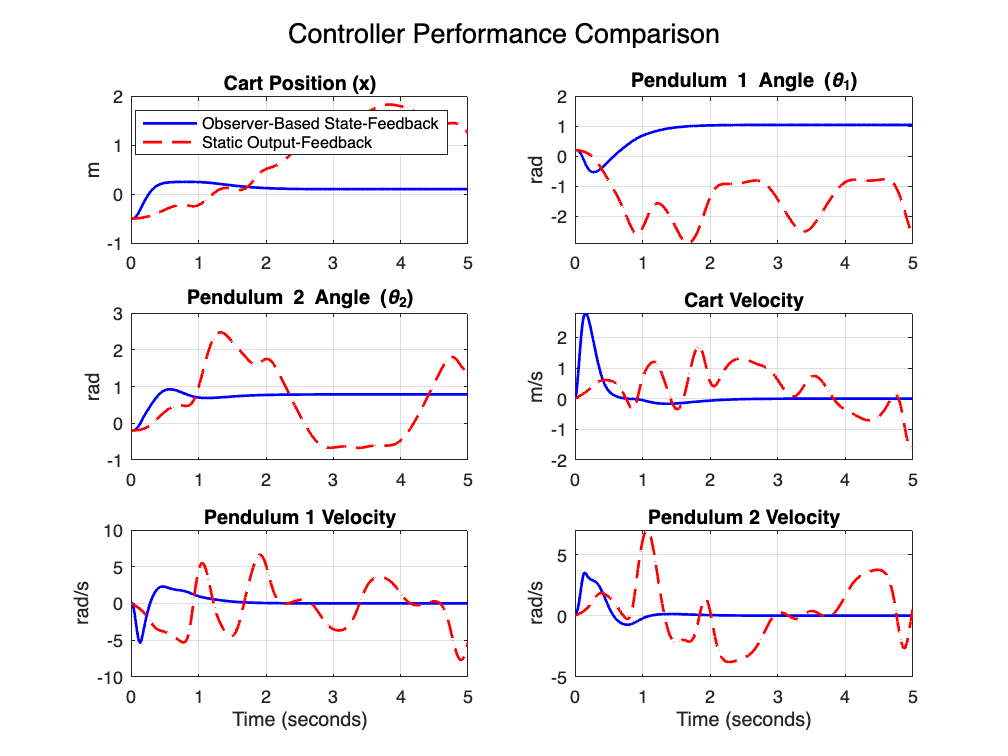


%zero Initial Condition for Observer states
x_hat_init = zeros(6, 1);
 
x_ex_init = [x_init; x_hat_init]; 

dynamics_observer_based = @(t, x) ...
    [f_handle_3u(x(1:6), -K_x * (x(7:12) - xe_vals) + ue); ... % Plant: x_dot = f(x, -K*x_hat)
    (A_u3 - B_u3*K_x - L*C_u3)*(x(7:12) - xe_vals) + L*C_u3*(x(1:6)-xe_vals)]; % Observer dynamics

%Alternative way as disscues in Calss with z and x
% dynamics_observer_based = @(t, x, z) ...
%     [f_handle_3u(x, -K_cvx * z + ue); ... % Plant: x_dot = f(x, -K*x_hat)
%     (A_u3 - B_u3*K_cvx - L*C_u3)*z + L*C_u3*(x-xe_vals)]; % Observer dynamics


[T_obs, XZ_obs] = ode45(dynamics_observer_based, tspan, x_ex_init);

X = XZ_obs(:, 1:6);

% Simulation 2


dynamics_output_feedback = @(t, x) f_handle_3u(x, -K_o * C_u3 * (x - xe_vals) + ue);

[T_of, X_of] = ode45(dynamics_output_feedback, tspan, x_init);




%% --- 3. Generate Comparison Plots ---
figure('Name', 'Controller Performance Comparison');
subplot_titles = {'Cart Position (x)', 'Pendulum 1 Angle (\theta_1)', 'Pendulum 2 Angle (\theta_2)', 'Cart Velocity', 'Pendulum 1 Velocity', 'Pendulum 2 Velocity'};
ylabels = {'m', 'rad', 'rad', 'm/s', 'rad/s', 'rad/s'};
title('compare its performance against the output feedback controller.')

for i = 1:6
    subplot(3, 2, i);
    plot(T_obs, X(:, i), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(T_of, X_of(:, i), 'r--', 'LineWidth', 1.5);
    title(subplot_titles{i});
    ylabel(ylabels{i});
    grid on;
    if i > 4
        xlabel('Time (seconds)');
    end
    if i == 1
        legend('Observer-Based State-Feedback', 'Static Output-Feedback', 'Location', 'best');
    end
    hold off;
end
sgtitle('Controller Performance Comparison');

**Fazit:**

**As disscussed earlier Ky is not stabalizing and Kx with oberserver shows realy good performance**

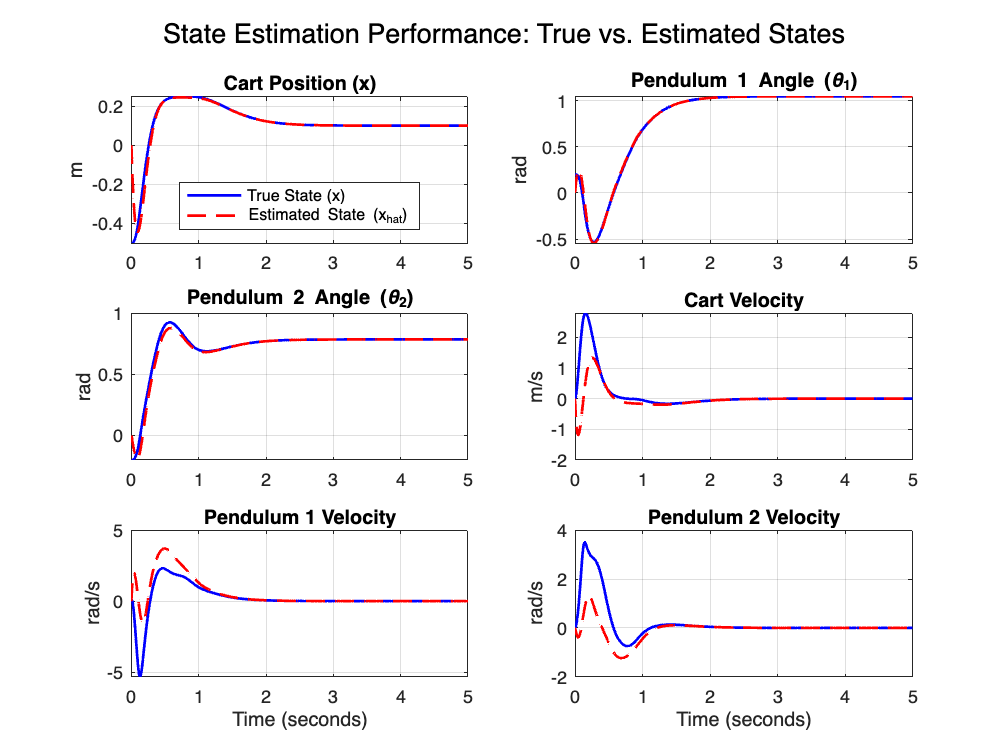

X_hat = XZ_obs(:, 7:12);

% Create a new figure for the comparison
figure('Name', 'State Estimation Performance: True vs. Estimated States');


% Define titles and labels for the subplots
subplot_titles = {'Cart Position (x)', 'Pendulum 1 Angle (\theta_1)', 'Pendulum 2 Angle (\theta_2)', 'Cart Velocity', 'Pendulum 1 Velocity', 'Pendulum 2 Velocity'};
ylabels = {'m', 'rad', 'rad', 'm/s', 'rad/s', 'rad/s'};

% Loop through each of the 6 states to create a subplot
for i = 1:6
    subplot(3, 2, i);
    
    % Plot the true state (solid blue line)
    plot(T_obs, X(:, i), 'b-', 'LineWidth', 1.5);
    hold on;
    
    % Plot the estimated state (dashed red line)
    plot(T_obs, X_hat(:, i), 'r--', 'LineWidth', 1.5);
    
    % Add formatting
    title(subplot_titles{i});
    ylabel(ylabels{i});
    grid on;
    
    % Add x-label only to the bottom plots
    if i > 4
        xlabel('Time (seconds)');
    end
    
    % Add a legend to the first subplot only for clarity
    if i == 1
        legend('True State (x)', 'Estimated State (x_{hat})', 'Location', 'best');
    end
    
    hold off;
end
sgtitle('State Estimation Performance: True vs. Estimated States' );

## Output for 3D Animation



%  physical parameters
l1 = 0.5; 
l2 = 0.75; 
g = 9.81;

% Cart dimensions 
cart_width = 0.5;
cart_height = 0.25;


x_res = timeseries(X(:,1), T_obs);
Theta1_res = timeseries(X(:,2), T_obs);
Theta2_res = timeseries(X(:,3), T_obs);


save("Funwork3_Gery_Results", "A_u3", "B_u3", "C_u3", "D_u3", "L", "f_u3", "state_vector", "input_vector", "xe_vals", "ue")
